close all 
clear all
clc

Absorptionskoeffizienten

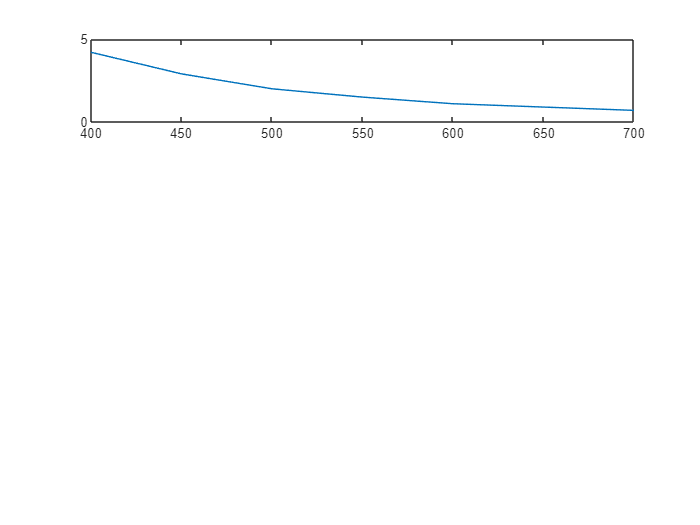

% Tabelle 1
n1_1 = [350;400;450;500;550;600;650;700;750;800;900;1000;1100]; % nm
n1_2 = [400;500;600;700;800;900;1000;1100]; % nm

quelle10_epi1 = [4.2;2.9;2;1.5;1.1;0.9;0.7]; % 400-700 nm
quelle10_epi2 = [15;10;7;4.5;3;2.5;2.5]; % 400-700 nm

quelle2_epi1 = [26.36;13.84;7.79;5.73;3.01;1.58;0.89;0.49;0.35]; % 400-800 nm
quelle2_epi2 = [12.96;7.07;3.08;2.58;1.71;0.8;0.45;0.17]; 

quelle10_dermis1 = [9;6;3.5;2.5;2;1.5;1.5]; % 400-700 nm
quelle10_dermis2 = [17.8;5.66;1.5;3.38;0.56;0.13;0.07]; % 400-700 nm

quelle2_dermis1 = [13.82;9.31;8.37;7.86;6.94;6.57;6.52]; % 400-700 nm
quelle2_dermis2 = [9.13;3.36;1.72;1.53;1.22;0.83;0.79;0.46]; %

% Tabelle 2
n2 = [470;530;660;770;810;940;1050]; % nm

quelle2_sc = [17.28;11.63;10.47;9.83;8.67;8.21;8.15]; % 400-700 nm
quelle3_sc = [1.49;1.01;0.49;0.3;0.23;0.17;0.14];

quelle3_pd = [7.19;8.73;0.36;0.29;0.42;0.51;0.68];
quelle3_rd = [6.88;8.52;0.26;0.23;0.42;0.55;0.83];

% Tabelle 3
n3_1 = [633;700;750;800;850;900;950;1000]; % nm
n3_2 = [470;530;660;770;810;940;1020;1050]; % nm

quelle2_hypo = [0.12;0.09;0.09;0.08;0.09;0.12;0.15;0.12];
quelle3_knochen = [1.26;1.004;0.667;0.237;0.213;0.244;0.248;0.518];
quelle3_muskel = [4.06;4.15;1.28;1.06;1.11;1.61;0.98;1];
quelle2_muskel = [1.23;0.48;0.41;0.28;0.3;0.32;0.46;0.51];

% Tabelle 4
n4 = [660;770;810;940;1020;1050]; % nm

quelle3_wasser = [0.0032;0.019858;0.26737;0.36;0.52;0.885];
quelle3_HbO2 = [170.5;209.1;1.5;3;4;6.5;6.1;4.9];
quelle3_Hb = [82.9;178.2;16.4;7.3;4.5;4.3;2.8;2.2];
quelle3_mel = [834.6;559.4;269.4;161.3;136.2;83;63.2;57.4];


% Visualisierung
figure;
h1 = subplot(4,1,1);
plot(n1_1(2:8),quelle10_epi1);

fontsize(h1,15,"pixels");

Unrecognized function or variable 'fontsize'.

hold on;
plot(n1_1(2:8),quelle10_epi2);
plot(n1_1(2:10),quelle2_epi1);
plot(n1_2,quelle2_epi2);
plot(n1_1(2:8),quelle2_sc);
plot(n2,quelle3_sc);
grid minor;
title('Absorptionskoeffizienten \mu_a für Epidermis und SC');
xlabel('Wellenlänge in nm');
legend('Epidermis [11]','Epidermis [11]','Epidermis [2]','Epidermis [2]','SC [2]','SC [3]');

h2 = subplot(4,1,2);
plot(n1_1(2:8),quelle10_dermis1);
fontsize(h2,15,"pixels");
hold on;
plot(n1_1(2:8),quelle10_dermis2);
plot(n1_1(2:8),quelle2_dermis1);
plot(n1_2,quelle2_dermis2);
plot(n2,quelle3_pd);
plot(n2,quelle3_rd);
plot(n3_1,quelle2_hypo);
grid minor;
title('Absorptionskoeffizienten \mu_a für Dermis, Stratum Papillare & Reticulare und Hypodermis');
xlabel('Wellenlänge in nm');
legend('Dermis [11]','Dermis [11]','Dermis [2]','Dermis [2]','SP [3]','SR [3]','Hypodermis [2]');

h3 = subplot(4,1,3);
plot(n3_2,quelle3_knochen);
fontsize(h3,15,"pixels");
hold on;
plot(n3_2,quelle3_muskel);
plot(n3_1,quelle2_muskel);
plot(n4,quelle3_wasser);
grid minor;
title('Absorptionskoeffizienten \mu_a für Knochen, Muskel und Wasser');
xlabel('Wellenlänge in nm');
legend('Knochen [3]','Muskel [3]','Muskel [2]','Wasser [3]');

h4 = subplot(4,1,4);
plot(n3_2,quelle3_HbO2);
fontsize(h4,15,"pixels");
hold on;
plot(n3_2,quelle3_Hb);
plot(n3_2,quelle3_mel);
grid minor;
title('Absorptionskoeffizienten \mu_a für HbO_2, Hb und Melanin');
xlabel('Wellenlänge in nm');
legend('HbO_2 [3]','Hb [3]','Melanin [3]');

p1=get(h1,'position');
p2=get(h2,'position');
p3=get(h3,'position');
p4=get(h4,'position');
height=p1(2)+p1(4)-p4(2);
h5=axes('position',[p4(1) p4(2) p4(3) height],'visible','off');
h_label=ylabel('Absorptionskoeffizient \mu_a in cm^{-1}','visible','on');
fontsize(h_label,20,"pixels");

print('-dpdf','Absorb','-fillpage');

Streuungskoeffizient

% Tabelle 5
quelle2_sc_s = ones(8,1) * 500;
quelle2_epi_s = [210.4;156.3;121.6;93.01;74.7;63.76;55.48;54.66];
quelle2_dermis_s = [212.7;159.9;124.1;92.24;77.22;63.09;55.98;53.62];

% Tabelle 6
quelle3_knochen_s = [308.8;315.4;296.6;280;267.1;215.7;191.8];
quelle3_muskel_s = [85.7;85.2;85.6;83.8;81.1;79.8;76.7];
quelle2_muskel_s = [89.2;88.2;83.3;79;73.56;71.3;66.7];

% Visualisierung
figure;
h6 = subplot(2,1,1);
plot(n1_1(1:8),quelle2_sc_s);
fontsize(h6,15,"pixels");
hold on;
plot(n1_1(1:8),quelle2_epi_s);
plot(n1_1(1:8),quelle2_dermis_s);
grid minor;
title('Streuungskoeffizienten \mu_s für SC, Epidermis und Dermis');
xlabel('Wellenlänge in nm');
ylim([0 510]);
legend('SC [2]','Epidermis [2]','Dermis [2]');

h7 = subplot(2,1,2);
plot(n2,quelle3_knochen_s);
fontsize(h7,15,"pixels");
hold on;
plot(n2,quelle3_muskel_s);
plot(n1_1(4:10),quelle2_muskel_s);
grid minor;
title('Streuungskoeffizienten \mu_s für Knochen und Muskel');
xlabel('Wellenlänge in nm');
legend('Knochen [3]','Muskel [3]','Muskel [2]');

p6=get(h6,'position');
p7=get(h7,'position');
height=p6(2)+p6(4)-p7(2);
h8=axes('position',[p7(1) p7(2) p7(3) height],'visible','off');
h_label2=ylabel('Streuungskoeffizient \mu_s in cm^{-1}','visible','on');
fontsize(h_label2,15,"pixels");

print('-dpdf','Streu','-bestfit');

Reduzierter Streuungskoeffizient

% Tabelle 7
n7_1 = [350;400;450;500;550;600;650;700]; % nm
n7_2 = [400;450;500;550;600;650;700;750;800;900;1000;1100;1200]; % nm
n7_3 = [400;500;600;700;800;900;1000;1100;1200]; % nm
n7_4 = [400;450;500;550;600;630;650;700;740]; % nm

quelle2_sc_strich = [48.99;48.44;45.24;41.93;38.69;35.02;32.21;28.93];
quelle2_epi_strich_1 = [31.73;30.11;28.27;26.82;25.29;24.14;22.97;22.09;21.27];
quelle2_epi_strich_2 = [106.2;70.6;51.4;42.7;36.8;33.6;30.6;29.2;26.5];
quelle10_epi_strich = [100;90;70;60;50;50;45;13;13];

quelle10_dermis_strich = [75;60;45;35;30;30;30;25;25];
quelle2_dermis_strich = [76.8;46.2;32.2;26.4;22.5;20.1;18.6;17.6];

% Tabelle 8
n8 = [633;700;750;800;850;900;950;1000]; % nm

quelle2_hypo_strich = [12.58;12.1;11.75;11.4;11.17;10.95;10.81;10.71];
quelle2_muskel_strich = [8.94;8.18;7.71;7.04;6.67;6.21;5.9;5.73];

% Visualisierung
figure;
h9 = subplot(2,1,1);
plot(n7_1,quelle2_sc_strich);
fontsize(h9,15,"pixels");
hold on;
plot(n7_2(1:9),quelle2_epi_strich_1);
plot(n7_3,quelle2_epi_strich_2);
plot(n7_4,quelle10_epi_strich);
grid minor;
title('Reduzierte Streuungskoeffizienten \mu_s\prime für SC und Epidermis');
xlabel('Wellenlänge in nm');
legend('SC [2]','Epidermis [2]','Epidermis [2]','Epidermis [11]');

h10 = subplot(2,1,2);
plot(n7_4,quelle10_dermis_strich);
fontsize(h10,15,"pixels");
hold on;
plot(n7_3(1:8),quelle2_dermis_strich);
plot(n8,quelle2_hypo_strich);
plot(n8,quelle2_muskel_strich);
grid minor;
title('Reduzierte Streuungskoeffizienten \mu_s\prime für Dermis, Hypodermis und Muskel');
xlabel('Wellenlänge in nm');
legend('Dermis [11]','Dermis [2]','Hypodermis [2]','Muskel [2]');

p9=get(h9,'position');
p10=get(h10,'position');
height=p9(2)+p9(4)-p10(2);
h11=axes('position',[p10(1) p10(2) p10(3) height],'visible','off');
h_label3=ylabel('Reduzierter Streuungskoeffizient \mu_s\prime in cm^{-1}','visible','on');
fontsize(h_label3,15,"pixels");

print('-dpdf','Streu_red','-bestfit');

g

% Tabelle 9
n9_1 = [240;400]; % nm
n9_2 = [350;400;450;500;550;600;650;700]; % nm
n9_3 = [300;540;577]; % nm

quelle5_sc = [0.58;0.78];
quelle2_sc_g = [0.902;0.903;0.91;0.916;0.923;0.93;0.936;0.942];
quelle5_epi = [0.71;0.78;0.786];
quelle2_epi_g = [0.702;0.712;0.728;0.745;0.759;0.774;0.787;0.804];
quelle2_dermis_g = ones(8,1) * 0.715;

% Tabelle 10
n10_1 = [470;530;660;770;810;940;1050]; % nm
n10_2 = [500;550;600;650;700;750;800];

quelle3_knochen_g = ones(7,1) * 0.93;
quelle3_muskel_g = [0.7748;0.7949;0.8813;0.9013;0.9088;0.9112;0.9187];
quelle2_muskel_g = [0.903;0.909;0.926;0.93;0.93;0.931;0.93];

% Visualisierung
figure;
h12 = subplot(2,1,1);
plot(n9_1,quelle5_sc);
fontsize(h12,15,"pixels");
hold on;
plot(n9_2,quelle2_sc_g);
plot(n9_3,quelle5_epi);
plot(n9_2,quelle2_epi_g);
plot(n9_2,quelle2_dermis_g);
grid minor;
title('Anisotropiefaktor g für SC, Epidermis und Dermis');
xlabel('Wellenlänge in nm');
legend('SC [4]','SC [2]','Epidermis [4]','Epidermis [2]','Dermis [2]',"Position", [0.13988,0.7477,0.20536,0.16905]);

h13 = subplot(2,1,2);
plot(n10_1,quelle3_knochen_g);
fontsize(h13,15,"pixels");
hold on;
plot(n10_1,quelle3_muskel_g);
plot(n10_2,quelle2_muskel_g);
grid minor;
title('Anisotropiefaktor g für Knochen und Muskel');
xlabel('Wellenlänge in nm');
legend('Knochen [3]','Muskel [3]','Muskel [2]',"Position", [0.6875,0.25008,0.19464,0.10476]);

p12=get(h12,'position');
p13=get(h13,'position');
height=p12(2)+p12(4)-p13(2);
h14=axes('position',[p13(1) p13(2) p13(3) height],'visible','off');
h_label4=ylabel('Anisotropiefaktor g','visible','on');
fontsize(h_label4,15,"pixels");

print('-dpdf','An','-bestfit');